# Actividad 2: control cinemático de robots móviles

## Abstracción del robot a un arreglo

Para tener un fácil acceso a variables intrínsecas del robot, hicimos un arreglo. Este contiene $R\to$ radio de la llanta, $L\to$Distancia entre llantas, posX y posY, que representa su coordenada en el eje x, y en el plano.

% Erase any prior data
clear all;
close all;
clc;

% Create robot
L = 0.5;
R = 1;
initX = 0;
initY = 0;
intit_w = 0;

global robot d_t pathFollowed;
robot = [ L, R, initX ,initY, intit_w];

% Set velocities
lw_v = 0.2

lw_v = 0.2000

rw_v = 0.3

rw_v = 0.3000


% Simulation space:
final_t = 5;
init_t = 0;
d_t = 0.01;

% Keep path points:
pathFollowed = animatedline('LineStyle', '--');

%% Test basic trasformation
% while init_t < final_t
%     wheelVelCtrl(rw_v, lw_v)
%     init_t = init_t + d_t;    
% end

pos = [1,0.5]

pos =     1.0000    0.5000


angle = pi/2

angle = 1.5708

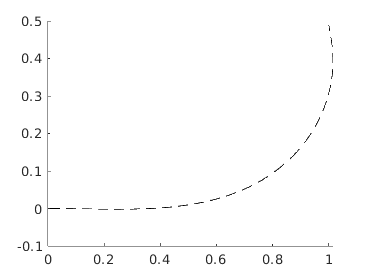

robotCtrl(pos, angle)

## Control por velocidad de llantas independientes

function wheelVelCtrl(rw_dv, lw_dv)
    global robot d_t pathFollowed;
    % L = robot(1)
    % R = robot(2)
    % w = robot(5)

    V = robot(2)*(rw_dv + lw_dv)/2;
    w = robot(2)*(rw_dv - lw_dv)/robot(1);
    
    x_d = V* cos(robot(5));
    y_d = V* sin(robot(5));
    w_d = w;

    % Update robot pos:
    robot(3) = robot(3) + x_d*d_t; % TODO: reference d_t
    robot(4) = robot(4) + y_d*d_t;
    % Update robot angle:
    robot(5) = robot(5) + w_d*d_t;

    % Plot robot position
    figure(1)
    %scatter(robot(3),robot(4))
    
    % hold on
    addpoints(pathFollowed, robot(3), robot(4));
    drawnow

end

## Control de ángulo dirección


$$\upsilon =\frac{R}{2}\;\left(v_r +v_l \right)\vdots \;$$


    
$$\frac{2\upsilon }{R}=v_r +v_l$$



$$\omega =\frac{R}{L}\left(v_r -v_l \right)\vdots$$


    
$$\frac{\omega L}{R}=v_r -v_l$$


Al resolver el sistema de ecuaciones pasado, obtenemos la velocidad que debe tener cada llanta para llegar al punto deseado. Esto viene dado por las ecuaciones:

$v_r =\frac{2\upsilon +\omega L}{2R}$ y $v_l =\frac{2\upsilon +\omega L}{2R}$

## Control por velocidad y dirección

function Vel_AngleCtrl(vel, angle)
    % L = robot(1)
    % R = robot(2)
    v_r = (2*vel + angle*robot(1))/(2*robot(2));
    v_l = (2*vel - angle*robot(1))/(2*robot(2));

    wheelVelCtrl(v_r, v_l);
end

## Selección de puntos 

Se nos solicita que el robot sea capaz de desplazarse de un punto a otro, es por esto que necesitamos un método para hacer esta elección

function pointSelection ()

end

## Control clásico de robot

Una vez que contamos con una manera de mover al robot, puntos en un plano a los que queremos ir, así como angulos finales que debemos tener en esas posiciones, necesitamos implementar un control que por medio del "feedback" llegue de manera autónoma a los sitios requeridos. 

function robotCtrl(desPos, desAngle)
    
    global robot d_t;

    % Robot actual coordenates:
    % x = robot(3)
    % 4 = robot(4)
    final_t = 5;
    init_t = 0;

    % Control constants
    kt = 1;
    ka = 2;
    kb = -1;

    while init_t < final_t
        x_e = robot(3) - desPos(1);
        y_e = robot(4) - desPos(2);
        
        % ArcTan(x/y) = angle |   desY - presentY, desX - presentX |
        objectiveAngle = atan2(desPos(2) - robot(4), desPos(1) - robot(3));
        
        thetaref = pi/2;
        thetae = robot(5) - thetaref;
    
        rho = sqrt(x_e^2 + y_e^2);
        alpha = objectiveAngle - robot(5);
        beta = -thetae - alpha;
    
    
    
        v = kt*rho;
        omega = ka*alpha + kb*beta;
    
        if v > 1
            v = 1;
        end
        if omega > pi/2
            omega = pi/2;
        end
        if omega < -pi/2
            omega = -pi/2;
        end
    
        vr = v + 0.5*robot(1)*omega;
        vl = v - 0.5*robot(1)*omega;
        
        wheelVelCtrl(vr, vl);
        init_t = init_t + d_t;
    end
end